clc
clear
close all

t=3;t1=-t/2:0.01:t/2;
t2=-3*t/2-0.01:0.01:3*t/2+0.01;
s1=unit(t1+1)-unit(t1-1);
r1=t1.*t1;
x1=s1.*r1;
out=[];
for i=1:3
out=[out x1];
end
subplot(5,1,1);plot(t2,out);title('Original Signal'); 
grid;
m=100;
for i=1:m
k2=-i:i;
for h=1:length(k2)
f=k2(h);
basis=exp((1i).*f.*((2*pi)/t).*t1); 
a1(h)=(1/t).*trapz(t1,x1.*basis);
end
subplot(5,1,2);
stem(k2,real(a1));
title('Real part of the coefficients of fourier series');
grid;subplot(5,1,3);
stem(k2,imag(a1));
title('Imaginary part of the coefficients of Fourier series');
grid;
reconstruct=zeros(size(t1));
for h=1:length(k2)
f=k2(h);
basis25=exp((1i).*(f).*((2*pi)/t).*(t1));
reconstruct=reconstruct+(a1(h).*basis25);
end
subplot(5,1,4);
plot(t1,x1);hold on;
plot(t1,reconstruct);
hold off;title('Reconstructed signal');pause(0.01);drawnow;
e(i)=mean((abs(reconstruct- x1)).^2);
end

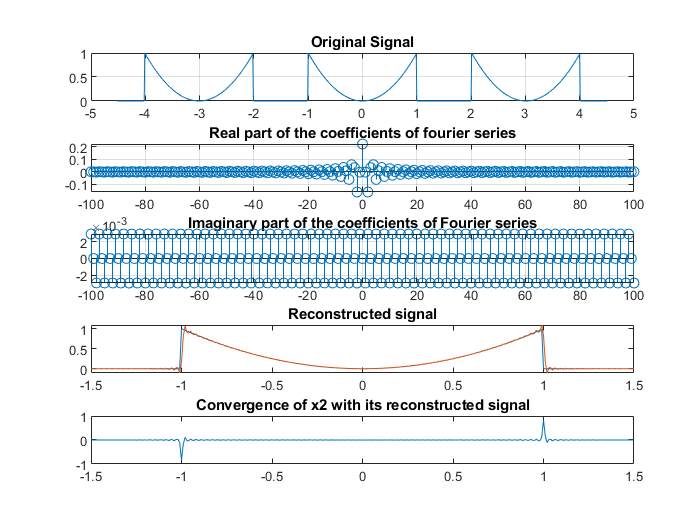

subplot(5,1,5);stem(1:m,e);title('Error');
plot(t1,reconstruct-x1);title('Convergence of x2 with its reconstructed signal');
m=100;
% Lets take some random errors

reconerr_2=abs(e(m)-e(m-1));disp('reconerr_2=');disp(reconerr_2);

reconerr_2=
   4.4405e-05

